load('UnitaryFakeProfile.mat');
load('UnitaryFakeProfile_T0_1_many.mat');
%Load the Library with all functions
addpath('../Library')
%Define the physical constant
mli=9.988346*10^-27;  %kg
hbar=1.0545718*10^(-34); %SI
hh=2*pi*hbar;%SI Planck constant
omega=23.9*2*pi; %in rad/s
pixellength=1.44*10^-6; %in m
sigma0=0.215*10^-12/2; %in m^2
warning('off','all');
[ KappaTildeT_U, PTildeT_U, TTildeT_U, ~, ~] = VirialUnitarity( );

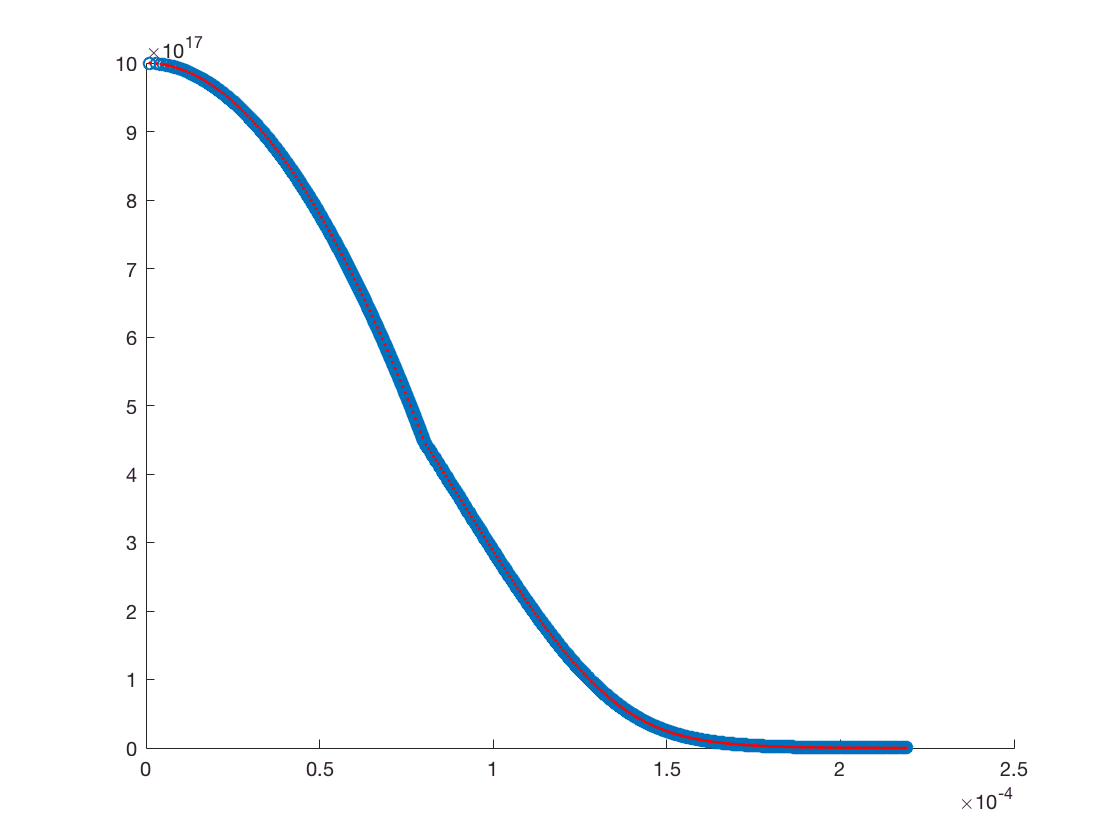

% [zbin,nbin,~] = BinLinear(z_TTilde_vec,n_vec_TTilde,6e-6,1.8e-5,(1.8e-5)/5000 );
% zbin=z_TTilde_vec;nbin=n_vec_TTilde;

Xgrid=1e-6:(2.2e-4)/300:2.2e-4;

[zbin,nbin,~,~]=BinGrid(z_TTilde_vec,n_vec_TTilde,Xgrid,0 );

scatter(z_TTilde_vec,n_vec_TTilde)

hold on
plot(zbin,nbin,'r.');
hold off

zbin(isnan(nbin))=[];
nbin(isnan(nbin))=[];
nbin=nbin/2;
Vbin=0.5*mli*omega^2*zbin.^2;
[Vsort,B]=sort(Vbin);
zsort=zbin(B);
nsort=nbin(B);

[~,~,Pt]=GetPvsV( nsort,Vsort);
% Kt=GetKappavsVPolyPoints(nsort,Vsort,1,1);
%Kt=GetKappavsVPolyGlobal( nsort,Vsort,10);
Kt=GetKappavsVFiniteD( nsort,Vsort,1);

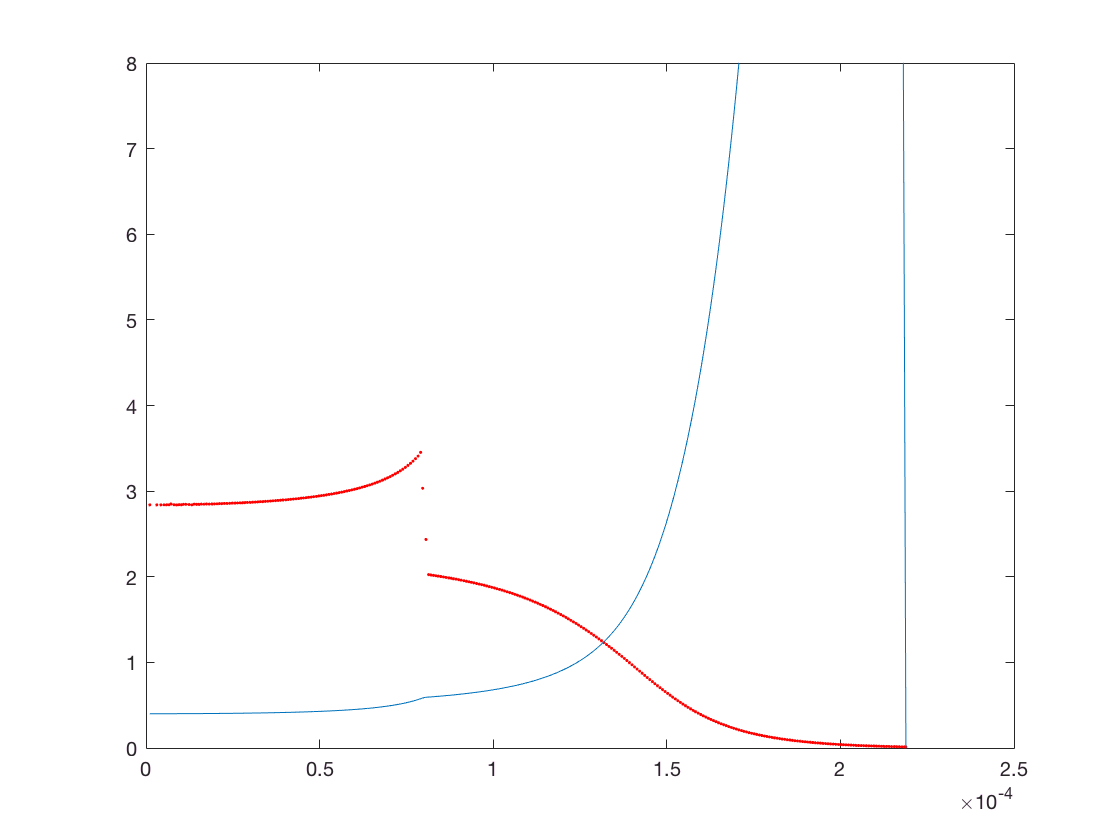

% load('UnitaryFakeProfile.mat');
plot(zsort,Pt);
hold on
%plot(z_TTilde_vec,PTilde_vec(196:end))
hold off
ylim([0,8])

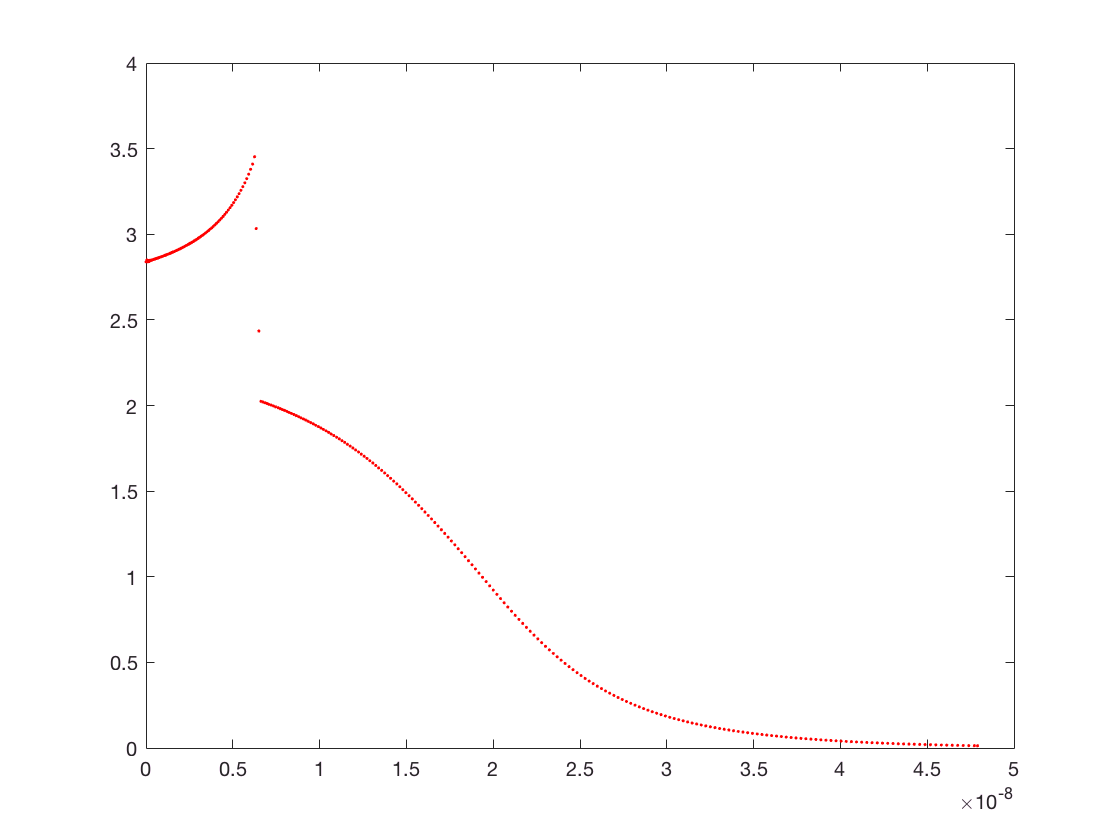


plot(zsort.^2,Kt,'r.');
hold on
%plot(z_TTilde_vec,KappaTilde_vec(196:end))
ylim([0,4])
hold off

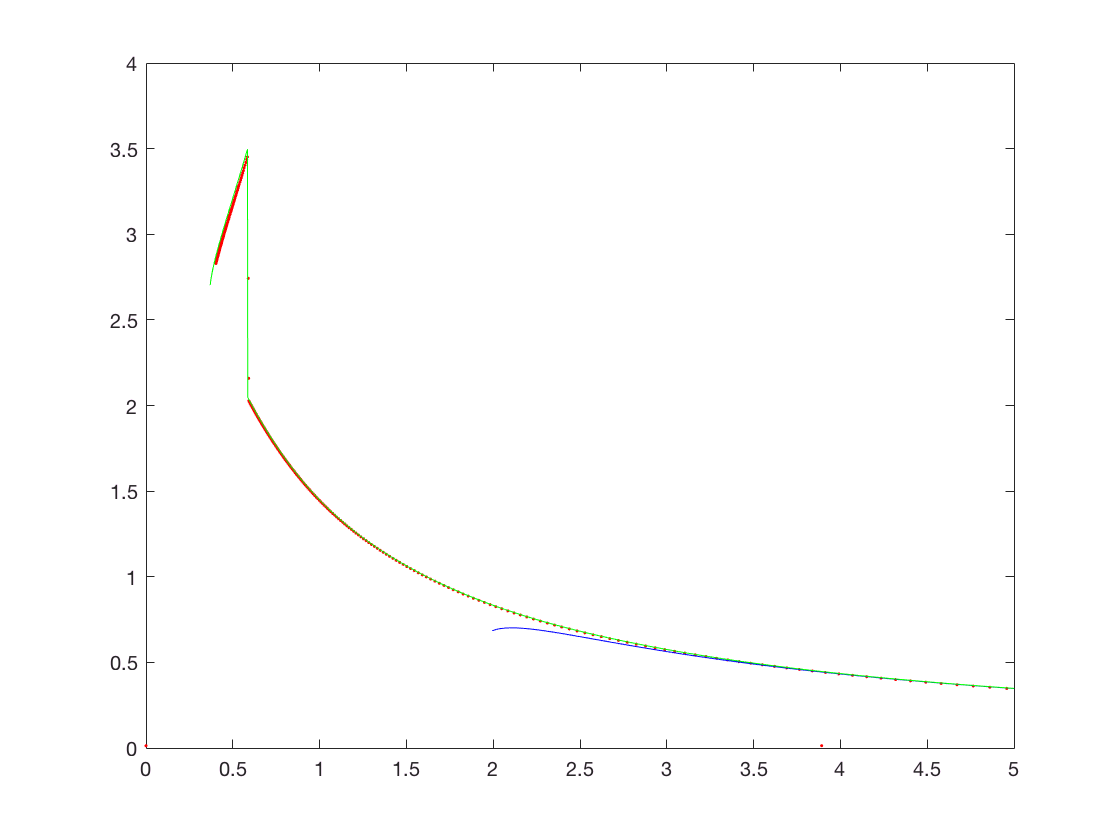

plot(Pt,Kt,'r.')
hold on
plot(PTildeT_U,KappaTildeT_U,'b');
plot(PTilde_vec,KappaTilde_vec,'g');
hold off
xlim([0,5]);ylim([0,4])

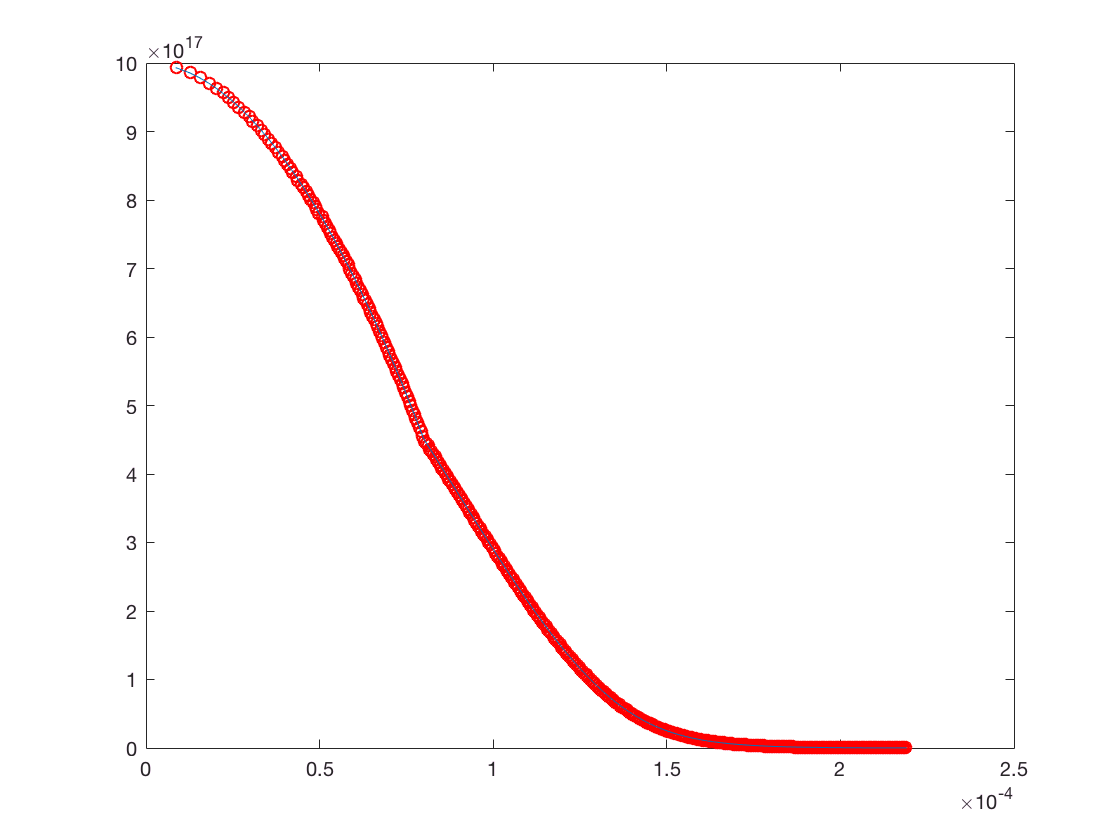

load('UnitaryFakeProfile_T0_1_many.mat');
plot(bin_z_TTilde_vec,bin_n_vec_TTilde,'ro');
hold on
plot(z_TTilde_vec,n_vec_TTilde);
hold off